# Mètode de la biscció

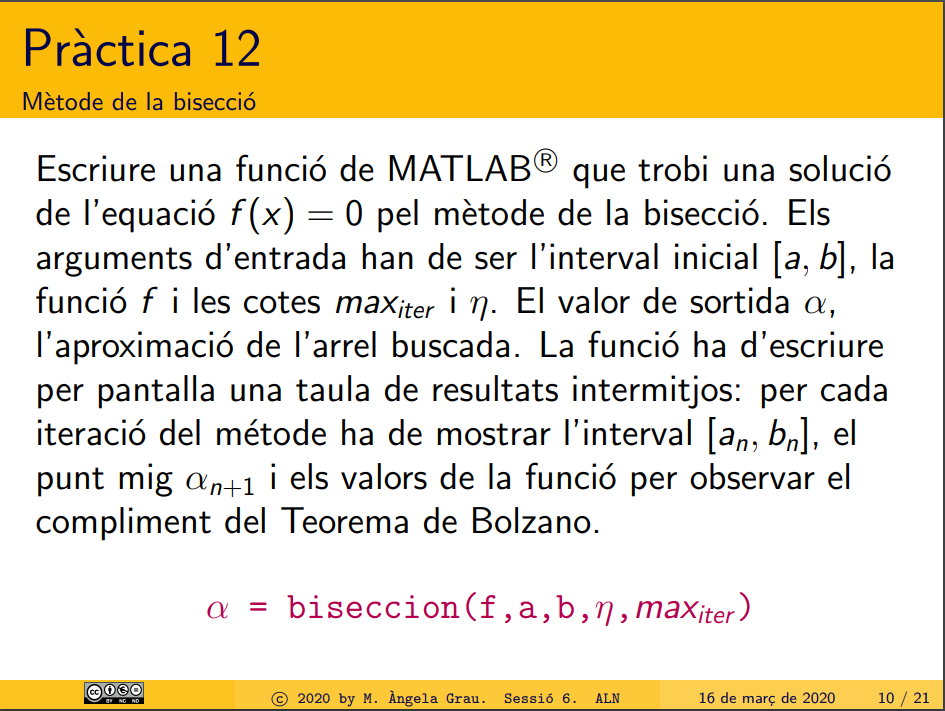

a=-1.4; b=-1.3; 
tol = 0.001; nmax = 10;
f=@(t)t.^3-t+1;
[~]= bisection(f,a,b,tol,nmax);


t =

     []



t = 7×5 table
            iter                      a                        b                      alpha                   falpha        
    ____________________    _____________________    _____________________    _____________________    _____________________

    0.00000000000000e+00    -1.40000000000000e+00    -1.30000000000000e+00    -1.35000000000000e+00    -1.10375000000000e-01
    1.00000000000000e+00    -1.35000000000000e+00    -1.30000000000000e+00    -1.32500000000000e+00    -1.20312500000086e-03
    2.00000000000000e+00    -1.32500000000000e+00    -1.30000000000000e+00    -1.31250000000000e+00     5.15136718750000e-02
    3.00000000000000e+00    -1.32500000000000e+00    -1.31250000000000e+00    -1.31875000000000e+00     2.53098144531245e-02
    4.00000000000000e+00    -1.32500000000000e+00    -1.318750000

# Mètode de newton

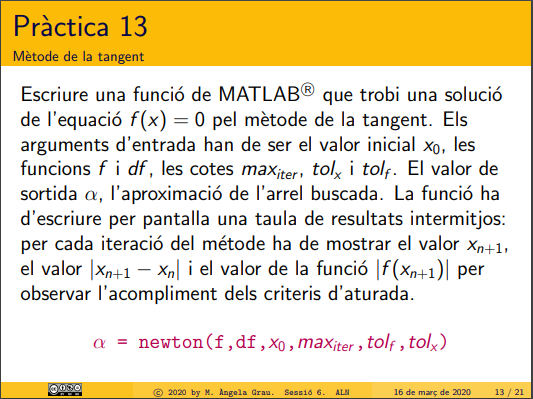

format long E
f = @(t)t.^3-t+1;
df = @(t) 3*t.^2-1;
x0 = -1.4;
tol = 0.00005;
nmax = 6;
[alpha]= newton(f ,df , x0,nmax,tol,tol)

t = 2×4 table
            iter                      x                     falpha                alphamenosx     
    ____________________    _____________________    _____________________    ____________________

    0.00000000000000e+00    -1.32950819672131e+00    -2.05199157638742e-02    7.04918032786885e-02
    1.00000000000000e+00    -1.32473920221220e+00    -9.06037830101791e-05    4.76899450910895e-03


alpha =     -1.324739202212202e+00


# Mètode de la secant

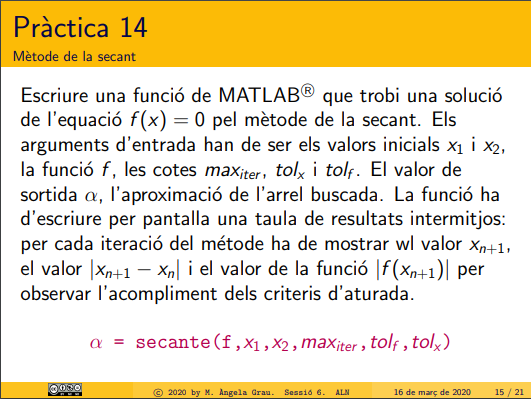

format short g, 
f = @(t)t.^3-t+1;
a = -2; b = -1; 
tol = 0.00005; nmax = 15;
[zero]= secant(f,a,b,tol,eps, nmax)

xnmenos1 =     -2


t = 5×4 table
    iter     xmas1       fxmas1       xnmas1menosxn
    ____    _______    ___________    _____________

     0      -1.1667         0.5787        -0.16667 
     1      -1.3956       -0.32263        -0.22894 
     2      -1.3137       0.046687        0.081948 
     3       -1.324      0.0029911       -0.010359 
     4      -1.3247    -3.1101e-05     -0.00070913 


zero =       -1.3247


# Mètode de la regula falsi

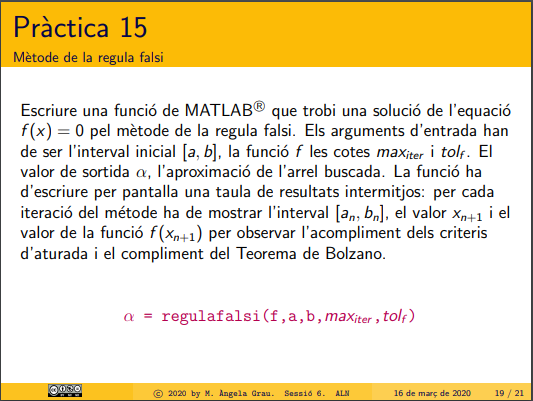

format long E
a=-1.4; b=-1.3; 
tol = 0.00005; nmax = 15;
f=@(t)t.^3-t+1;
[zero]= regulafalsi(f,a,b,tol,nmax)

t = 13×5 table
            iter                      a                        b                       xn                       fxn         
    ____________________    _____________________    _____________________    _____________________    _____________________

    0.00000000000000e+00    -1.40000000000000e+00    -1.30000000000000e+00    -1.32304250559284e+00     7.13403510643462e-03
    1.00000000000000e+00    -1.40000000000000e+00    -1.32304250559284e+00    -1.32460606085070e+00     4.77147296291225e-04
    2.00000000000000e+00    -1.40000000000000e+00    -1.32460606085070e+00    -1.32471049162210e+00     3.18379191894813e-05
    3.00000000000000e+00    -1.40000000000000e+00    -1.32471049162210e+00    -1.32471745917864e+00     2.12406814803501e-06
    4.00000000000000e+00    -1.40000000000000e+00    -1.32471745

Output argument "xalpha" (and maybe others) not assigned during call to "sesion6>regulafalsi".

function [alpha] = bisection(f,a,b,eta,maxiter)
    if (f(a)*f(b) >= 0)
        display('Error valores a y b');
    end
    iter = 0;
    t = []
    while(abs(b-a) > eta && iter < maxiter && abs(b-a) > eps)
        alpha = (a+b)/2;
        f_alpha = f(alpha);
        t = [t; iter a b alpha f_alpha];
        iter = iter+1;
        if (sign(f(alpha)) == sign(f(b)))
            b = alpha;
        else
            a = alpha;
        end
    end
    t = array2table(t,'VariableNames',{'iter','a', 'b', 'alpha', 'falpha'})
end
function [alpha]= newton(f ,df, a ,maxiter,tolf,tolx)
    iter =  0;
    alpha = a - f(a)/df(a);
    t = [iter  alpha f(alpha) (alpha-a)];
    while (iter < maxiter && abs(alpha-a) >= tolx && abs(f(alpha)) >= tolf )
        a = alpha;
        alpha = a - f(a)/df(a);
        iter = iter +1;
        t = [t;iter  alpha f(alpha) (alpha-a)];
    end
    alpha = t(end-1, 2);
    t = array2table(t(1:end-1,:),'VariableNames',{'iter','x', 'falpha', 'alphamenosx'})
end
function [alpha]= secant(f,a,b,tolx,tolf,maxiter)
   iter = 0;
   xnmenos1 = a
   xn = b;
   xnmas1 = xn-f(xn)*((xn-xnmenos1)/(f(xn)-f(xnmenos1)));
   t = [iter  xnmas1 f(xnmas1) (xnmas1-xn)];
   while (iter < maxiter && abs(xnmas1-xn) >= tolx && abs(f(xnmas1)) >= tolf )
        xnmenos1 = xn;
        xn = xnmas1;
        xnmas1 = xn-f(xn)*((xn-xnmenos1)/(f(xn)-f(xnmenos1)));
        iter = iter +1;
        t = [t; iter  xnmas1 f(xnmas1) (xnmas1-xn)];
   end
   alpha = t(end-1, 2);
   t = array2table(t(1:end-1,:),'VariableNames',{'iter','xmas1', 'fxmas1', 'xnmas1menosxn'})
end

function [xalpha] = regulafalsi(f,a,b,beta,maxiter)
    iter = 0;
    t = [];
    while(abs(b-a) > beta && iter < maxiter && abs(b-a) > eps)
        alpha= (f(b)*a-f(a)*b)/(f(b)-f(a));
        t = [t; iter a b alpha f(alpha)];
        iter=iter+1;
        if(sign(f(alpha)) == sign(f(b)))
            b=alpha;
        else
            a=alpha;
        end
    end
    t = array2table(t,'VariableNames',{'iter','a', 'b', 'xn', 'fxn'})
end

